% Question 3: Using the functions we created, write a program that allows
% the user to specify the initial configuration of a rigid body by T, a
% screw axis specified by {q, s, h} in fixed frame and theta. The program
% should calculate the final configuration 

% disp('Hello, welcome to the rigid body simulator. Enter all values as 3 dimensional row vectors')
% q = input('First, enter coordinates representing the location of the screw axis in spatial frame:');
% s = input('Input a unit vecotr representing the screw axis direction:');
% h = input('What is the pitch of the screw axis?:');
% q = input('First, enter coordinates representing the location of the screw axis in spatial frame:');
% r1 = input('Enter the basis vector B_x, this is the first column of the orientation matrix:')
% r2 = input('Enter the basis vector B_y, this is the second column of the orientation matrix:')
% r3 = input('Enter the basis vector B_y, this is the third column of the orientation matrix:')

% R = [r1' r2' r3']
% if checkRot(R) == false
%     disp("exit program")
% end


ans = 1

norm


T1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


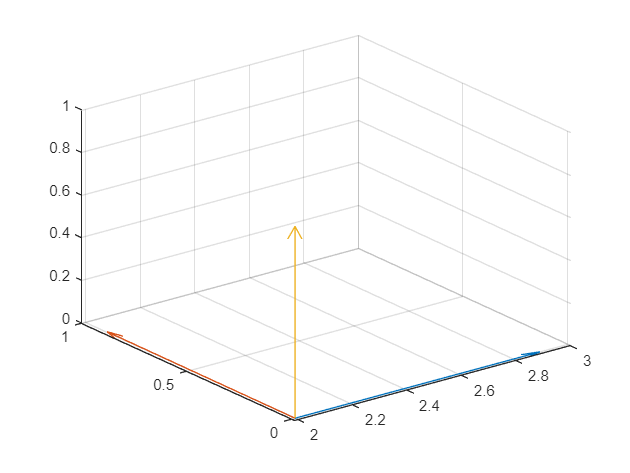



%%%% Algorithm Description : Given T and {q s h} we can get S (screw axis) as follows:
%   since infinite combinations for v and w (omega) arbitrarily set w to 1
%   and let h be the angular speed, theta dot is 1

% Once we find S, we get matrix exponential e^{Stheta} = "A"
% Final config  T1 = A*T
% e^(Stheta) looks like  [ [e^(w*theta) G_theta] , [0 I] ]


%%%% Test Case for Final Draft %%%
% % R = [[1 0 0]' [0 1 0]' [0 0 1]']; p = [2 0 0]';
% % T = cat(1, [R p], [0 0 0 1])
% % theta = pi; % th means theta
% % pi
% % thetas = [theta/4 theta/2 3*theta/4 theta] % th means vector of theta's for intermediate

%%%%% Second part of the program %%%%
% thetas = [theta/4 theta/2 3*theta/4 theta] % th means vector of theta's for intermediate
% w = s;
% wsk = skewSym(w); %skew symmetric representation of omega axis "w hat"
% v = -1*wsk*q' + h.*s'
% S = [w v']'; I = eye(3);
% 
% for i = 1:4
%     th = thetas(i);
%     Gtheta = I*th + (1 - cos(th))*wsk + ((th - sin(th))*wsk*wsk); % make this a function ?
%     pA = Gtheta*v; RA = Rot(w,th);
%     A = cat(1, [RA pA], [0 0 0 1]);
%     % Loop through intermediate positions:
%     T1 = A*T
% end
% % final position is stored in T1

% Initial Body Frame Configuration :
% B = [[-1 0 0 4],
%       [0 1 0 .4], 
%       [0 0 -1 0],
%       [0 0 0 1]]
%s = [2/sqrt(3)  12/sqrt(3)  2/sqrt(3)];
%s = [1/sqrt(3)  1/sqrt(3)  1/sqrt(3)];


% ======= Setting Different Test Cases Here ========================%%%
q = [0 0 0];
s = [0 0 1];
h = 2;
theta = pi;    

% Initial Configuration of Body Frame %
B = [[1 0 0 2],
       [0 1 0 0], 
       [0 0 1 0],
       [0 0 0 1]];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%% Calculations Begin HERE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
plotFrame(B); % Shows us the initial configuration

figs = []; thetas = parse(theta);
S = getScrew(q,s,h);

v =      0     0     2


S =      0     0     1     0     0     2


S =      0     0     1     0     0     2


ans = 1

norm


ans = 1

norm


ans = 1

norm


ans = 1

norm


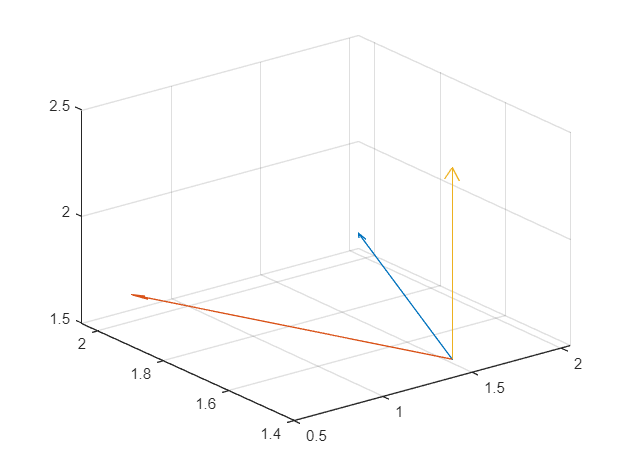

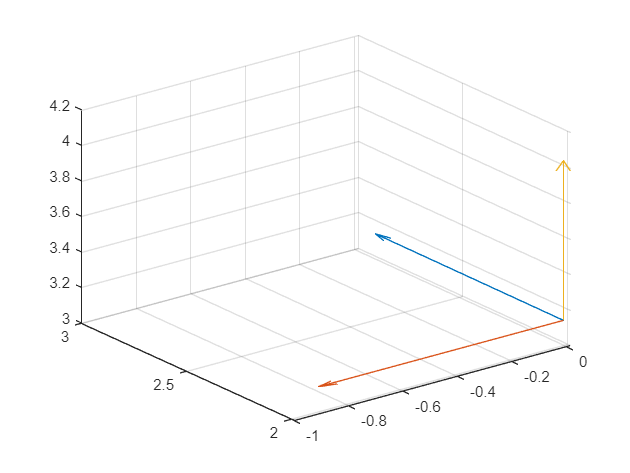

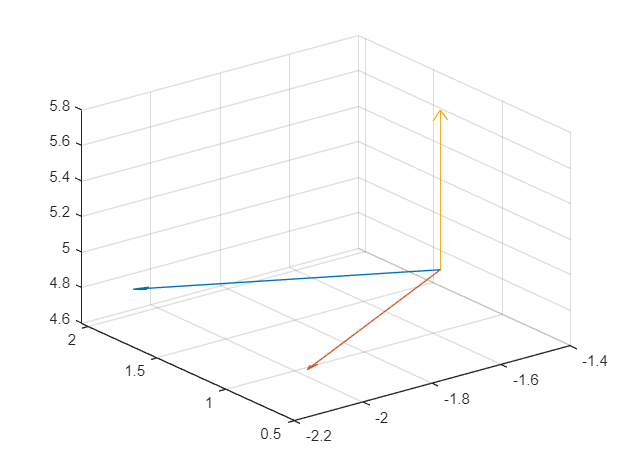

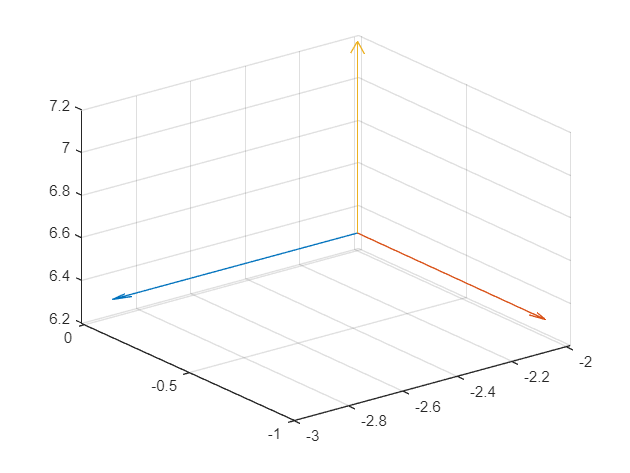

% This will iterate through 4 intermediate positions and plot the
% transformations "along the way"
for i = 1:4
    th = thetas(i);
    T = chaslesMozzi(S, th, h);    % Stepwise Transformation
    % Loop through intermediate positions:
    B1 = T*B;
    figs = [figs plotFrame(B1)];
end


%% This will perfrom the full transformation and display. Also plots final view %%%
Bf = T*B

Bf =    -1.0000   -0.0000         0   -2.0000
    0.0000   -1.0000         0    0.0000
         0         0    1.0000    6.2832
         0         0         0    1.0000


plotFrame(T*B);

% This gets the inverse of the configuration which will move us back to home (origin) ===%
Inv = invertSE3(Bf)    % Compare this matrix to T1 below

Inv =    -1.0000    0.0000         0   -2.0000
   -0.0000   -1.0000         0         0
         0         0    1.0000   -6.2832
         0         0         0    1.0000


[theta, S] = se3Logarithm(Inv)   % Screw axis that takes us back to origin

R =    -1.0000    0.0000         0
   -0.0000   -1.0000         0
         0         0    1.0000


p =    -2.0000
         0
   -6.2832


   -1.0000    0.0000         0
   -0.0000   -1.0000         0
         0         0    1.0000



ans = 1

w =      0     0     1


norm


v =    -0.0000
    1.0000
   -2.0000


S =          0         0    1.0000   -0.0000    1.0000   -2.0000


theta = 3.1416

theta = 3.1416

S =          0         0    1.0000   -0.0000    1.0000   -2.0000


T1 = chaslesMozzi(S, theta, h)   % Full transformation, i guess any finite ptich works here?

ans = 1

norm


T1 =    -1.0000   -0.0000         0   -2.0000
    0.0000   -1.0000         0   -0.0000
         0         0    1.0000   -6.2832
         0         0         0    1.0000


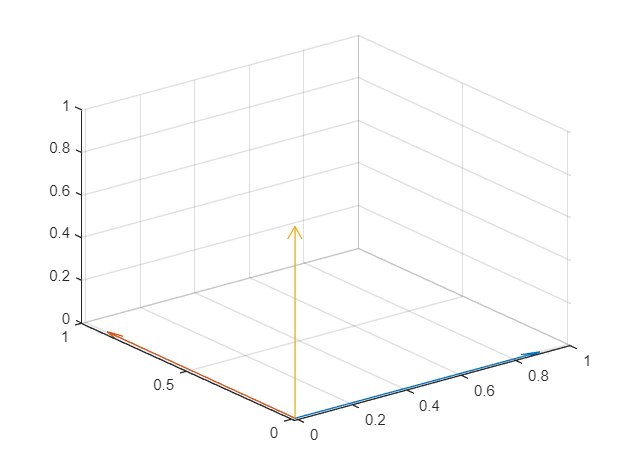

plotFrame(Inv*Bf);

plotFrame(T1*Bf);
Inv*Bf  % one final double check --> this should be the identity matrix

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


function S = getScrew(q,s,h)  % be sure to keep track of pitch as well
    if (length(q) ~= 3 | length(s) ~= 3 | length(h) ~= 1)
        disp('dimensins of input may be incorrect');
        S = [0 0 1 0 0 0]
    else
        if isUnit(s) == false
            disp('s hat was not a unit vector, angular velocity is assumed to be:')
            disp(norm(s))
        end
        if h == inf
            v = s/norm(s);
            w = [0 0 0];
            S = [w v];
        else
            v =  (skewSym(-1.*s)*q')' + (h.*s)
            %disp((skewSym(-1.*s)*q')')
            %disp((h.*s))
            % more fun to use skew symmetric but cross gives same
            w = s ;  %v = cross(s,q) + (h.*s)
            S = [w v]    %mod = norm(S)  %sanity check
            S = S./norm(w)
        end
    end
end

%%%% Given a screw axis and pitch , return Homogenous T %%%%%%%%%%%%%
%% since it is private, we will assume a valid screw axis is passed w/o checks%%%
%% 2 cases depending on pitch: pure rotation or case with translation
function T = chaslesMozzi(S, theta, h)
    th = theta; w = S(1:3);  
    R = Rot(w,th);  I = eye(3);  v= S(4:6);
    %R  % uncomment for a check on R
    if h == inf
        v
        v = v/norm(v)
        T = cat(1, [I th.*v'], [0 0 0 1]); % pure translation
    else  
        w = w/norm(w); wsk = skewSym(w);
        norm(w)
        disp('norm')
        G = I*th + (1 - cos(th))*wsk + ...
                    (th - sin(th)).*wsk*wsk;
        p = G*v'; % translation along screw
        T = cat(1, [R p], [0 0 0 1]);
    end
end

function thetas = parse(theta)
    step = theta/4;
    for i = 0:3
        thetas(i+1) = step +i*step;
    end
end

function fig = plotFrame(T1)
    p = T1(:,4);
    c1 = T1(:,1); c1 = c1/norm(c1);
    c2 = T1(:,2); c2 = c2/norm(c2);
    c3 = T1(:,3); c3 = c3/norm(c3);
    figure;
    quiver3(p(1), p(2), p(3), c1(1), c1(2), c1(3) );
    hold on;
    quiver3(p(1), p(2), p(3), c2(1), c2(2), c2(3) );
    quiver3(p(1), p(2), p(3), c3(1), c3(2), c3(3) );
    hold off; %zlim([0,5]), xlim([0,5]), ylim([0,5])
    fig = figure;
end

function T_inv = invertSE3(T)
    R = T(1:3, 1:3); p = T(1:3 , 4);
    pinv = (-R')*p;
    T_inv = cat(1, [R' pinv], [0 0 0 1]);
end

function [theta, S] = se3Logarithm(T)
    R = T(1:3, 1:3)
    p = T(1:3, 4)
    I = eye(3);
    if R == I
        w = [0 0 0];
        v = (p/norm(p))';
        theta = norm(p)
        S = [w v]
    else
        [w, theta] = rot2AxisAngle(R);
        norm(w)
        w
        disp("norm")
        wsk = skewSym(w);
        G_inv = 1/theta*I - (1/2)*wsk + (1/theta - 1/2*cot(theta/2)).*(wsk*wsk);
        v = G_inv*p
        S = [w v']
        theta
    end
end



% for i = 1:4
%     th = thetas(i);
%     Gtheta = I*th + (1 - cos(th))*wsk + ((th - sin(th))*wsk*wsk); % make this a function ?
%     pA = Gtheta*v; RA = Rot(w,th);
%     A = cat(1, [RA pA], [0 0 0 1]);
%     % Loop through intermediate positions:
%     T1 = A*T
% end

%%%%%%%% Question 1 Test Cases: %%%%%%%%%%%%%%%%%%%%%%%%%%

% All parts test cases:
% (1) Verify that it is a valid Rotation Matrix
%   Non-Singular, columns are orthogonal and determinant is 1

% % disp("Test Case 1:  ");  R = [[1 1 1]; [2 2 2]; [1 2 1]]; [w,theta] = rot2AxisAngle(R)  % Singular Matrix
% % disp("Test Case 2:  ");  R = eye(3); [w,theta] = rot2AxisAngle(R)                       % Identity Matrix
% % disp("Test Case 3:  ");  R = [[0 -1 0]; [1 0 0]; [0 0 1]]; [w,theta] = rot2AxisAngle(R) % 90 deg about Z axis
% % disp("Test Case 4:  ");  R = [[1 0 0]; [0 -1 0]; [0 0 -1]]; [w,theta] = rot2AxisAngle(R) % Singularity: 180 deg about x axis
% % disp("Test Case 5:  ");  R = [[-1 0 0]; [0 1 0]; [0 0 -1]]; [w,theta] = rot2AxisAngle(R)  % Singularity: 180 deg about y axis
% % disp("Test Case 6:  ");  R = [[0 1 0]; [-1 0 0]; [0 0 1]]; [w,theta] = rot2AxisAngle(R) % Outside Range: 3*pi / 2 should return -90 deg rotation about Z axis
% % disp("Test Case 7:  ");  R = [[-1 0 0]; [0 -1 0]; [0 0 -1]]; [w,theta] = rot2AxisAngle(R) % left-handed matrix
% % disp("Test Case 7:  ");  
% % disp("Test Case 8:  ");  
% % disp("Test Case 9:  ");  



% Part A Test Cases:
% (2) The identity matrix should return theta = 0 and w undefined
% (3) Test Case with singularities, set theta to pi and 


% Part B
% Identity, 0 quaternion, permutation of axis


% % disp("Test Case 1:  ");  R = [[1 1 1]; [2 2 2]; [1 2 1]]; rot2Quat(R)    % Singular Matrix
% % disp("Test Case 1:  ");  R = eye(3);  rot2Quat(R)                         % Identity Matrix
% % disp("Test Case 2:  ");  R = [[0 -1 0]; [1 0 0]; [0 0 1]]; q3 = rot2Quat(R)   % 90 deg about Z axis
% % disp("Test Case 3:  ");  R = [[0 1 0]; [-1 0 0]; [0 0 1]]; q4 = rot2Quat(R) % -90 deg about z axis
% % disp("Test Case 4:  ");  R = [[1 0 0]; [0 -1 0]; [0 0 -1]]; rot2Quat(R)  % 180 deg about x axis
% % disp("Test Case 5:  ");  R = [[-1 0 0]; [0 1 0]; [0 0 -1]]; rot2Quat(R)  % 180 deg about y axis
% % %disp("Test Case 6:  ");  R = [[0 1 0]; [-1 0 0]; [0 0 1]]; rot2Quat(R)   % Outside Range: 3*pi / 2 should return -90 deg rotation about Z axis
% % %disp("Test Case 7:  ");  R = [[-1 0 0]; [0 -1 0]; [0 0 -1]];  rot2Quat(R) % left-handed matrix
% % disp("Test Case 6:  ");  quatMult(q3,q4)


%%%%%%%%%%%%%% Question 2 Test Cases %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% (a) Axis angle Test Cases
%% Sean, Can you do these? 
% (1)  Angles that are multiples of 2*pi should produce the same result
% (2)  If you use positive angle and the same negative angle, this should produce the same       result
% (2) theta = 0 should give the identity matrix
% (3) An Axis that is not length 1 : use an axis that has length 2*pi 
% (4) If input omega is None type or not a vector, then return the identity and display message
% (5) Test simple cases with known results :  axis (0,0,1) and theta = 90 degrees
% (6) Test another one of these simple cases: axis (1,0,0) theta is 90 or 180  
% (7)  Test that 2  45deg rotations about the same axis give a 90 degree rotation
% (8) Test the inverse rotation, pass the same axis, same angle but negative – multiply the  

% % disp("Test Case 1:  ");  w = [0,0,1] ; theta = pi/2; 
% % disp("Test Case 2:  ");  
% % disp("Test Case 3:  ");  
% % disp("Test Case 4:  ");  
% % disp("Test Case 5:  ");  
% % disp("Test Case 6:  ");  
% % disp("Test Case 7:  ");  
% % disp("Test Case 8:  ");  


%%%%%%% (b) quaternion representation Tests %%%%%%%%%%%%%%%%%%%%%%%%%%%
% check that identity quaternion
% check the 0 quaternion
% check permutation of axes ( a simple one -- try the i,j,k quaternions)
% we could also try simple linear combinations of each srqt(2)/2

% % a = sqrt(2)/2; b = sqrt(3)/3; c = sqrt(4)/4;
% % disp("Test Case 1:  "); quat2Rot([0,0,0,0])
% % disp("Test Case 2:  ");quat2Rot([1,0,0,0])
% % disp("Test Case 3:  ");quat2Rot([0,1,0,0])
% % disp("Test Case 4:  "); quat2Rot([0,0,1,0])
% % disp("Test Case 5:  "); R1 = quat2Rot([0,0,0,1])
% % disp("Test Case 6:  "); R2 = quat2Rot([0,a,0,a])
% % disp("Test Case 7:  "); R3 = quat2Rot([0,b,b,b])
% % disp("Test Case 8:  "); R4 = quat2Rot([c,c,c,c])
% % R5 = quat2Rot([c,-c,-c,-c]); % inverse
% % disp("Test Case 9:  "); R0 * R2
% % % based on the result, the R0 and R2 combined should
% % % produce a 90 degree rotation, let's check
% % R0 * R2
% % R1 * R2
% % R4 * R5
% % R2 * R6
% % 
% % c = [0,0,0,1]; b = [0,a,0,a]; Q = quatMult(c,b);
% % c = quaternion([0,0,0,1]); b = quaternion([0,a,0,a]); Q1 = c*b;
% % quat2Rot(Q)
% % quat2Rot(Q1)



%%%%%%%%%%% COMBINED TEST CASES  %%%%%%%%%%%%%%

%%% Quaternions %%%%%
% Combined Test Case 1 %
% % q1 = quaternion(cos(pi/2), 0, 0,sin(pi/2));
% % q2 = [cos(pi/2) , 0 , 0 , -sin(pi/2)];
% % R1 = quat2Rot(q1)
% % R2 = quat2Rot(q2)
% % R1*R2








% ============= Question 1 Functions ================ %
function [w,theta] = rot2AxisAngle(R)  % matrix logarithm
    if isRot(R) == false
        w = "undefined"; theta = 0;
        disp('Input to function was not a valid rotation matrix')
    else
        I = eye(3); t = trace(R);
        disp(R) % Comment out if cluttering 
        if (R == I) theta = 0; w = "undefined";  % omega is arbitrary in this case (meaningless)
        elseif (t == -1) 
            theta = pi; 
            % 3 cases, choose the one where we do not divide by 0
            if  ( 1/(sqrt(2*(1+R(1,1)))) ~= Inf ) % Case 1
                alpha = 1/(sqrt(2*(1+R(1,1))))
                w = alpha.*[1+R(1,1), R(2,1), R(3,1)];
                disp("here 1")
            elseif ( 1/(sqrt(2*(1+R(2,2)))) ~= Inf )  % Case 2
                alpha = 1/(sqrt(2*(1+R(2,2)))); 
                w = alpha.*[R(1,2), 1+R(2,2), R(3,2)];
                %disp("sing is here 2 ")
            else                                        % Case 3
                alpha = 1/(sqrt(2*(1+R(3,3))));
                w = alpha .* [R(1,3), R(2,3), 1+R(3,3)];
            end
        else
            theta = acos(.5*(t-1));
            w_hat = 1/(2*sin(theta)).* (R - R');
            norm(w_hat)
            disp("norm is here")
            w = [R(3,2) , R(1,3) , R(2,1)];
        end
    end
end

function isRot = isRot(R)
    r0 = R(1); r1 = R(2); r2 = R(3);
    i = [1,0,0]'; j = [0,1,0]'; k = [0,0,1]';
    check = dot(r0,r1) + dot(r0, r2) + dot(r1,r2); 
    if (det(R) ~= 1) isRot = false; disp('determinant')
    elseif (check > abs(1e-13)) isRot = false; disp('orthogonal') % numerical error possible, careful
    else isRot = true;
    end
end

%=================== Rotation Matrix to Quaternion Representation (Unique)=======%
% Hard-code formulas given in class
function Q = rot2Quat(R)
    Q = [1,0,0,0]; R  % display only
    if isRot(R) == false
            disp('Input to function was not a valid rotation matrix');
    else
        Q(1) = sqrt(R(1,1) + R(2,2) + R(3,3) + 1)/2;
        Q(2) = sign(R(3,2) - R(2,3))*sqrt(R(1,1) - R(2,2) - R(3,3) + 1)/2;
        Q(3) = sign(R(1,3) - R(3,1))*sqrt(R(2,2) - R(3,3) - R(1,1) + 1)/2;
        Q(4) = sign(R(2,1) - R(1,2))*sqrt(R(3,3) - R(1,1) - R(2,2) + 1)/2;
    end
end

% Another way is to convert to axis-angle first and then to quaternion
function Q = rot2Quat2(R)
    theta, w = Rot(R);
    Q = zeros(4); Q(1) = cos(theta)/2 ; Q(2:4) = sin(theta/2).*w
end


%=================== Rotation Matrices to Euler Angles ============================%
% formulas come from comparisons ... watch out for singularities ... some other conditions if that happens
% phi is the first rotation around z axis of the fixed frame ign{s} (body lines up with fixed)
% theta is the 2nd rotation around y-axis of the body frame {b}
% psi is the 3rd rotation about z-axis again but of body frame {b}

%=================== Rotation Matrices to Euler Angles ============================%
function [phi,theta, psi] = rot2Zyz(R)
    
    if isRot(R) == false
            phi = 0; theta = 0; psi = 0;
            disp('Input to function was not a valid rotation matrix');
    else
        % we don't use arc-cosine because it is important we get both value and quadrant correct
        if (R(2,3)~= 0) && (R(1,3) ~= 0) phi = atan2(R(2,3), R(1,3)); 
        else "idk -- use quaternion instead?"; end
        
        if  (R(3,3)~= 0) theta = atan2(sqrt(R(1,3)^2 + R(2,3)^2), R(3,3));
        else theta = pi/2; end % but couldn't it also be - pi/2 ?
        
        if (R(3,1) ~= 0 ) 
            psi = atan2(R(3,2), -R(3,1)); % also what about the 0 numerator ? what does atan2 choose?
        else "given theta is nonzero it implies"; psi = pi/2; end  % or -pi/2
    end
end


% Roll is about z-axis of the fixed frame {s}, Pitch is about y-axis of the fixed frame {s}
% and Yaw is about z-axis of the fixed frame {s}
function roll, pitch, yaw = ZYXRot(R)
    %r11,r21, r31, r32, r33 = R(1,1),  R(2,1),  R(3,1), R(3,2), R(3,3)
    if (R(1,1) ~= 0)
        roll = atan2(R(2,1), R(1,1))
    else
        thing = "idk exactly"
    end
    if (R(3,3) ~= 0)
        yaw = atan2(R(3,2), R(3,3));
        if (R(3,2) ~= 0)
            pitch = atan2(-R(3,1), sqrt( R(3,2)^2 + R(3,3)^2 ));
        end
    end
end

%% =============== Question 2 Functions =================================== %%

%================ Axis Angle to Rotation Matrix ============================%
% note that this is unique in the forward direction, pass in w as a vector,
% theta as a scalar. Returns unique SO3 matrix
function R = Rot(w, theta)
    if (size(w) ~= 3) | (isa(w,"double") == false)
        disp("Error: input axis was not a 3-dim vector. Returning Identity")
        R = eye(3); 
    end
    if (isUnit(w) == false) 
        w = (1/norm(w)).*w;
        theta = norm(w)*theta;
    end
    hat = skewSym(w); % Just apply Rodrigues Formula:
    R = eye(3) + sin(theta).*hat + (1-cos(theta)).*(hat*hat); 
end


%================ Quaternions to Rotation Matrices =============================%
% this way is hard-coding, here we are choosing 0 to pi
function R = quat2Rot(Q)
  if isa(Q, 'quaternion') % we can accept either format of quaternion
       [q0,q1,q2,q3] = parts(Q); 
       Q = [q0,q1,q2,q3];
  else 
      q0 = Q(1); q1 = Q(2); q2 = Q(3); q3 = Q(4);  
  end
  if (isUnit(Q) == false) % it must be a unit quaternion or else return err message and identity
    disp("Error: input must be a unit quaternion. Returning Identity")
    R = eye(3); 
  else
    R = [[(q0^2 + q1^2 - q2^2 - q3^2), 2*(q1*q2 - q0*q3)           ,          2*(q0*q2 + q1*q3) ]
         [2*(q0*q3 + q1*q2)          , (q0^2 - q1^2 + q2^2 - q3^2) ,          2*(q2*q3 - q0*q1) ]
         [2*(q1*q3 - q0*q2)          , 2*(q0*q1 + q2*q3)           , (q0^2 - q1^2 - q2^2 + q3^2)] ];
  end 
end

% this way ought to work as well, there is a double-cover. Here we are
% choosing 0 to pi
function R = quat2Rot2(Q) 
    if isa(Q, 'quaternion') % we can accept either format of quaternion
        [q0, q1,q2,q3] = parts(Q); 
    else 
        q0 = Q(1); q1 = Q(2); q2 = Q(3); q3 = Q(4);  
    end
    
    if (isUnit(Q) == false | (size(Q) ~= 4))
        disp("You must input a unit quaternion into this function")
        R = eye(3); 
    else
        theta = 2*acos(Q(1));
        if (theta == 0) w = [0,0,0]; else w = (1/sin(theta/2)).* Q(2:4); end
        R = Rot(w, theta);
    end
end

function Q = quatMult(p,q)
    q0 = q(1); q = q(2:4); p0 = p(1); p = p(2:4);
    vec = cross(p,q) + q0.*p  + p0.*q;
    Q = [q0*p0 - dot(p,q), vec];
end

function tf = isUnit(Q)  % have to be very precise since there is rounding error
    if abs(norm(Q) - 1) < 1e-15  % floating point precision (32 bit)
        tf = true;
    else 
        tf = false;
    end
end


%====================== Helper Functions ==============================%

% always assume 3 dimensional vector input
function w_hat = skewSym(w)
    w_hat = [[0    ,-w(3),  w(2)], 
             [w(3) , 0   , -w(1)], 
             [-w(2), w(1),  0   ]] ;
end

function s = sign(x)
    if (x < 0) s = -1; else s = 1; end  % note: if x 0 then s is +1
end





% elementary basis rotations
function Rz = RotZ(theta)
    Rz = [ [cos(theta) -sin(theta) 0];
           [sin(theta)  cos(theta) 0];
           [0           0          1] ]
end
function Ry = RotY(theta)
    Ry = [ [cos(theta)  0  sin(theta)];
           [0           1           0];
           [-sin(theta) 0  cos(theta)]]
end
function Rx = RotX(theta)
    Rx = [ [1       0                    0];
           [0      cos(theta)  -sin(theta)];
           [0      sin(theta)   cos(theta)]]
end



